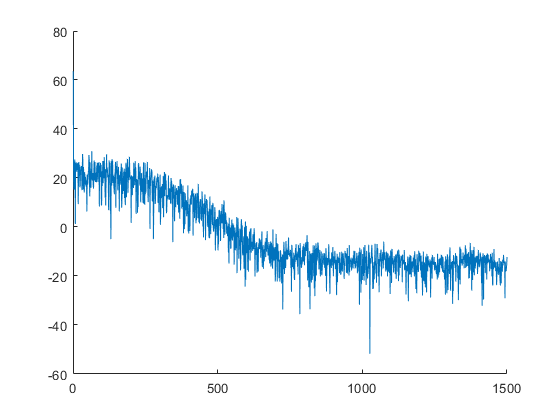

clear all
close all
clc

rng(4);

datasize = 3000;
inz = smoothdata(rand(datasize,1),'gaussian',10);


% plot(inz)

FY = mag2db(abs(fft(inz)));

figure;
hold on
plot(FY(1:floor(end/2)))
hold off


% Choose TT-ranks

n=3; m=3;
mn = n+m;

inlags=[1 2];
outlags =[0 1 2 4 8];

d=numel(inlags)+numel(outlags)-1;
% r = (min(min(mn.^[0:d],mn.^[d:-1:0]),maxrank));

synth = double(rand(mn*ones(1,d))>0.5);

% for i=1:d
% synth = (smoothdata(synth,i,'gaussian',3));
% end

TN = ttsvd(synth,0.001)

TN = struct with fields:
    core: {[1×6×6 double]  [6×6×36 double]  [36×6×195 double]  [195×6×36 double]  [36×6×6 double]  [6×6 double]}
      sz: [6×3 double]


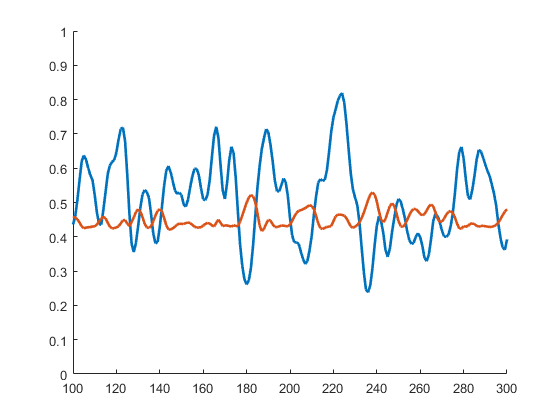


siminput = inz;
siminput(1:21)=heaviside(-10:10)/2;

simoutput = zeros(datasize,1);

% siminput = 1*ones(1000,1);
% siminput = 0.2*sin(1:0.01:11)'+0.5;

for j = 10:datasize
simfeaturez = [simoutput(j-outlags(2:end))' siminput(j-inlags(1:end))'];
% simfeaturez(simfeaturez<0)=0;
% simfeaturez(simfeaturez>1)=1;
simoutput(j) = evalspline(TN,simfeaturez,n,m);
end

figure
hold on
plot(siminput,'Linewidth',2)
plot(simoutput,'Linewidth',2)
% plot((inz(11)/simoutput(11))*simoutput)
hold off
axis([100 300 0 1])

noiso = [0.0001 0.001 0.005 0.01 0.05 0.1 0.2]

noiso =     0.0001    0.0010    0.0050    0.0100    0.0500    0.1000    0.2000


for period = 1:7
noize = noiso(period)*randn(size(simoutput));
simoutputnoise = simoutput+ noize;
simoutputnoise(simoutputnoise>1) = 1;
simoutputnoise(simoutputnoise<0) = 0;
SNR(period) = snr(simoutput(10:end)-mean(simoutput(10:end)),noize(10:end))

% figure
% hold on
% % plot(siminput)
% plot(simoutput,'Linewidth',2)
% plot(simoutputnoise)
% % plot((inz(11)/simoutput(11))*simoutput)
% hold off
% axis([0 200 -inf inf])


SNR = 47.4840


input = siminput(10:2000);
output = simoutputnoise(10:2000);
outputclean = simoutput(10:2000);

tinput = siminput(2001:end);
toutput = simoutput(2001:end);
toutputnoise = simoutputnoise(2001:end);


% plot(uEst)
% plot(yEst)
% for i =1:7
% uEst = [uEst ;(uEst+0.0*rand(size(uEst)))];
% yEst = [yEst ;(yEst+0.5*rand(size(yEst)))];
% end
% 
% yEst(yEst>10)=10;
% plot(uVal)
% plot(yVal)

% autocorr(uEst,1000)
% autocorr(yEst,1000)

% parcorr(uEst,1000)
% parcorr(yEst,1000)

Preprocessing Data

tic

% Choose the lags for the input
inlags=[1 2];
for l = 1:length(inlags)
u(:,l) = input(end-inlags(l)-(1900):end-inlags(l));
uv(:,l) = tinput(end-inlags(l)-(900):end-inlags(l));
end

% Choose the lags for the output, 0 is the estimated output
outlags=[0 1 2 4 8];
for l = 1:length(outlags)
y(:,l) = output(end-outlags(l)-(1900):end-outlags(l));
yv(:,l) = toutput(end-outlags(l)-(900):end-outlags(l));
end



Split test and training set

featurez = [y(:,2:end)  u];
zeta = y(:,1);

tfeaturez = [yv(:,2:end)  uv];
yt = yv(:,1);


Construct B-spline basis vectors


[N, d]=size(featurez); 

n = 3;                  %degree B-spline
m = 3;                  %Number of knot intervals
In = n+m;               %Number of B-splines

% Construct the basis vectors from the features
un = basisvectors(featurez,n,m);




Initialize tensor train -----------------------------------------------------------------

% Choose TT-ranks
maxrank =5;
r = (min(min(In.^[0:d],In.^[d:-1:0]),maxrank));

[TN,Vm,Vp] = initTT(un,r,d);


Show storage compression ratio


Pcount = (In)^d;                    %Original tensor size
dof = sum(prod(TN.sz,2));           %Degrees of freedom/ TT storage size.
disp(['Compression: ' num2str(dof/Pcount)])  %ratio

Compression: 0.014146



rez = [];

Optimize TT cores

lambda=1*10^-4;
gamma=0;

difforder=2;
MAXITR = 4*d;


% nselect = floor(logspace(log10(dof/N),0,MAXITR)*0.5*N);


% MAXITR = d;
nselect = ones([1,MAXITR])*N;
% plot(nselect)

[TN,Vm,Vp,res1,res2] = optimTT(TN,Vm,Vp,un,zeta,MAXITR,nselect,lambda,gamma,difforder);

    "iteration:"    "1"    "0.06416"

    "iteration:"    "2"    "0.10552"

    "iteration:"    "3"    "0.13649"

    "iteration:"    "4"    "0.16462"

    "iteration:"    "5"    "0.18836"

    "iteration:"    "6"    "0.21474"

    "iteration:"    "7"    "0.23746"

    "iteration:"    "8"    "0.26483"

    "iteration:"    "9"    "0.29369"

    "iteration:"    "10"    "0.32436"

    "iteration:"    "11"    "0.35014"

    "iteration:"    "12"    "0.3775"

    "iteration:"    "13"    "0.40632"

    "iteration:"    "14"    "0.43361"

    "iteration:"    "15"    "0.45457"

    "iteration:"    "16"    "0.48188"

    "iteration:"    "17"    "0.51003"

    "iteration:"    "18"    "0.53714"

    "iteration:"    "19"    "0.56975"

    "iteration:"    "20"    "0.60047"

    "iteration:"    "21"    "0.62762"

    "iteration:"

rez = [rez res1];
% 
% plot(res1)
% plot(res2)
% 
% trainerror = res1(end)

% plot(rez)

Evaluate Test data

% 
% yhattrain  = evalspline(TN,featurez,n,m);
% 
% figure;
% hold on
% % plot(zeta)
% plot(outputclean(end-1900:end))
% plot(yhattrain)
% hold off
% axis([0 inf -inf inf]);
% 
% erboiz = (yhattrain-zeta);
% VAF = 1-var(erboiz)/var(zeta)
% MSE = immse(yhattrain,zeta)



% 
% yhat = evalspline(TN,tfeaturez,n,m);
% erboi = (yhat-yt);
% % histogram((erboi)');
% VAF = 1-var(erboi)/var(yt)
% MSE = immse(yhat,yt)
% 
% figure
% hold on
% plot(yt)
% plot(yhat)
% hold off
% axis([0 inf -inf inf])
% 
% %  Visualize errors
% [sortout,Iss]=sort(yhat);
% figure
% hold on
% plot(yt(Iss))
% plot(sortout,'Linewidth',3)
% hold off
% 
% FY = mag2db(abs(fft(yhat)));
% FZ = mag2db(abs(fft(yt)));
% 
% figure;
% hold on
% plot(FZ(1:floor(end/2)))
% plot(FY(1:floor(end/2)))
% hold off


% plot(tinput)
% plot(toutput)

siminputz = tinput;
simoutputz = toutput;
numz = numel(outlags);
for j = 17:1000
simfeaturez = [simoutputz(j-outlags(2:end))' siminputz(j-outlags(2:end))'];
simfeaturez(simfeaturez<0)=0;
simfeaturez(simfeaturez>1)=1;
simoutputz(j) = evalspline(TN,simfeaturez,n,m);
end

figure
hold on
% plot(toutputnoise)
plot(toutput,'Linewidth',1)
plot(simoutputz,'Linewidth',1)
hold off
axis([0 200 -inf inf])

RMSE(period) = sqrt(immse(toutput,simoutputz))
VAF(period) = 1-var(toutput-simoutputz)/var(toutput)


toc
end

subplot(2,1,1)
plot(SNR,RMSE)
xlabel('SNR')
ylabel('RMSE')

subplot(2,1,2)
plot(SNR,VAF*100)

xlabel('SNR')
ylabel('VAF')